# Discrete-time Filtering

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Winter 2018.

Let's manipulate the phases of the sum of three sinusoid to get a feel for how phase changes can impact the time-domain features of a signal.

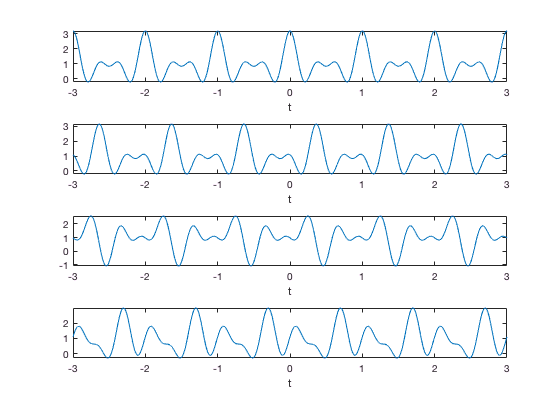

FS = 44100; %Sampling frequency
DURATION = 3;

tValues = linspace(-DURATION,DURATION,DURATION*FS);

%zero phase
phi1 = 0; phi2=0; phi3=0;
x1 = 1 + 1/2*cos(2*pi*tValues + phi1) + cos(4*pi*tValues + phi2) + 2/3*cos(6*pi*tValues + phi3);
subplot(4,1,1);
plot(tValues,x1);
xlabel('t');
axis tight;

%non-zero phase
phi1 = 4; phi2=8; phi3=12;
x2 = 1 + 1/2*cos(2*pi*tValues + phi1) + cos(4*pi*tValues + phi2) + 2/3*cos(6*pi*tValues + phi3);
subplot(4,1,2)
plot(tValues,x2);
xlabel('t');
axis tight;


%non-zero phase
phi1 = 6; phi2=-2.7; phi3=0.93;
x3 = 1 + 1/2*cos(2*pi*tValues + phi1) + cos(4*pi*tValues + phi2) + 2/3*cos(6*pi*tValues + phi3);
subplot(4,1,3)
plot(tValues,x3);
xlabel('t');
axis tight;

%non-zero phase
phi1 = 1.2; phi2=4.1; phi3=-7.02;
x4 = 1 + 1/2*cos(2*pi*tValues + phi1) + cos(4*pi*tValues + phi2) + 2/3*cos(6*pi*tValues + phi3);
subplot(4,1,4)
plot(tValues,x4);
xlabel('t');
axis tight

You can clearly see the difference. How well can we hear the difference? Let's speed the signals up and listen.

FS = 44100; %Sampling frequency
DURATION = 1.5;
tValues = linspace(0,DURATION,DURATION*FS);
omega = 2*pi*220;

%zero phase
phi1 = 0; phi2=0; phi3=0;
x1 = 1 + 1/2*cos(omega*tValues + phi1) + cos(2*omega*tValues + phi2) + 2/3*cos(3*omega*tValues + phi3);
sound(x1,FS)

%non-zero phase
phi1 = 6*omega; phi2=-2.7*omega; phi3=0.93*omega;
x2 = 1 + 1/2*cos(omega*tValues + phi1) + cos(2*omega*tValues + phi2) + 2/3*cos(3*omega*tValues + phi3);
sound(x2,FS)

%non-zero phase
phi1 = 1.2*omega; phi2=4.1*omega; phi3=-7.02*omega;
x3 = 1 + 1/2*cos(omega*tValues + phi1) + cos(2*omega*tValues + phi2) + 2/3*cos(3*omega*tValues + phi3);
sound(x3,FS)

You can hear a distinction between the sounds, but it is rather subtle.

## Linear and Nonlinear Phase systems

A system with nonlinear phase will do unpredictable things to a signal, even if it has unit gain. Let's try a simple all-pass system.

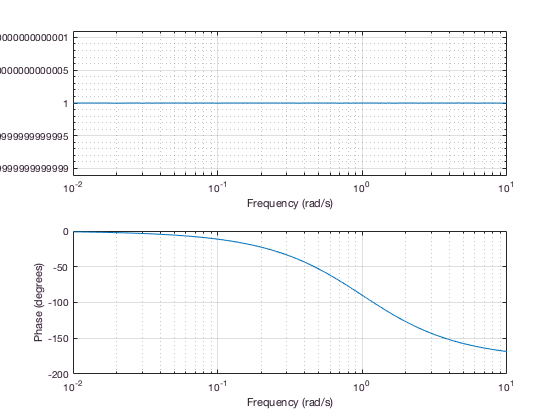

H = tf([-1 1],[1,1]); %Design the transfer function in the frequency domain
freqs([-1 1],[1 1]);

Very clearly an all-pass system, but with phase distortion. Let's see what it does to a simple pulse.

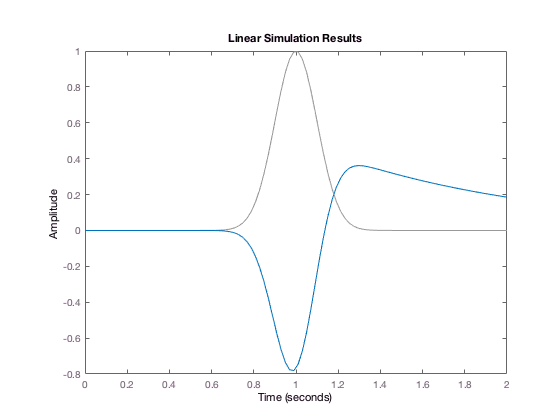

tValues = linspace(0,2,100);
x = exp(-50*(tValues-1).^2);
close all;
%plot(tValues,x);

lsim(H,x,tValues);

The output looks quite different from the input! Is such phase distortion audible?

DURATION = 3; %how many seconds
FS = 44100; %Sampling frequency
tValues = linspace(0,DURATION,FS*DURATION);
recObj = audiorecorder(FS,16,1); 
recordblocking(recObj, DURATION);
f = getaudiodata(recObj);

Let's listen to the output of this filter.

y = lsim(H,f,tValues);
sound(y,FS);

Turns out we can't hear much of a difference. This filter's phase is close enough to linear that it doesn't produce noticible distortion. We will need to arrange a larger phase non-linearity in order to get something that we can hear!

## Group delay

Let's try a more complex system, the series combination of three second-order all-pass filters.

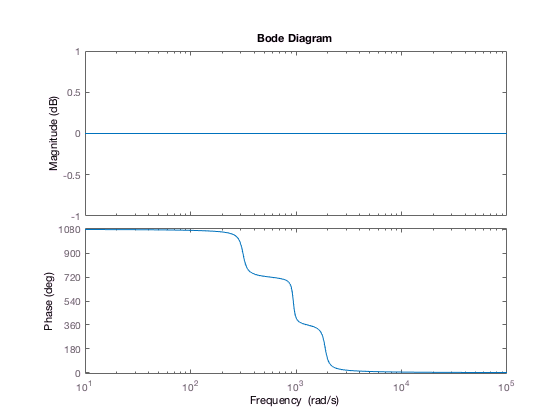

b1 = [1/315^2 -2*0.066/315 1];
a1 = [1/315^2 2*0.066/315 1];
H1 = tf(b1,a1);

b2 = [1/943^2 -2*0.033/943 1];
a2 = [1/943^2 2*0.033/943 1];
H2 = tf(b2,a2);

b3 = [1/1888^2 -2*0.058/1888 1];
a3 = [1/1888^2 2*0.058/1888 1];
H3 = tf(b3,a3);

bode(H1*H2*H3);

Here you can see that the group delay has three spikes, one at each of three different frequencies. Let's look at its impulse response.

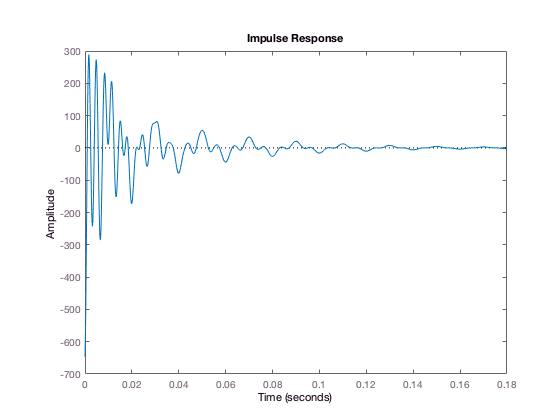

impulse(H1*H2*H3);

This impulse response "should" be a delta function -- after all, this is an all-pass system! Phase distortions cause *dispersion,* which smears out the impulse function in the time domain.

What does this do to our recorded signal?

y = lsim(H1*H2*H3,f,tValues);
sound(y,FS);

It's still difficult to hear much distortion if we aren't listening very carefully. The human auditory system is relatively robust to phase distortions.